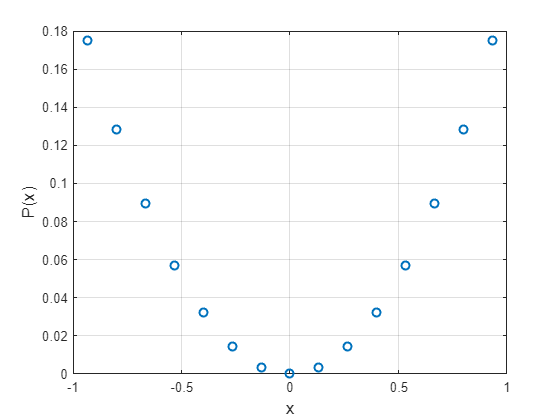

% ----------------------------------------------
% This program formulates the minimimal variance mechanism problem into a
% linear programing problem, and solves it using the built-in solver in Matlab.
% Comments are adquent in the code. 
% If you have any question,
% please feel free to contact Fei Wei at feiwei@nus.edu.sg
% ----------------------------------------------

close all
clear

% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 2; %the ratio amax/(xmax-xmin)

xmax = 1;
N = 15; % Total number of bins in [-xmax,xmax]
x_bin_size = 2*xmax/N;
x_grid = linspace(-xmax+0.5*x_bin_size,xmax-0.5*x_bin_size,N);

% We assign a distribution to X\in x_grid
% In the write-up, this is the data distribution

% x_P = ones(1,N)/N; % Uniform distribution

x_P = x_grid.^2;
x_P = x_P./ sum(x_P);

% x_P = x_grid-min(x_grid);
% x_P = x_P./sum(x_P);

figure
plot(x_grid,x_P,'o',LineWidth=1.5);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on


% [totalVariance,pMatrix] = opt_variance(eps,r,axRatio,x_grid,x_P);

% For testing, we sample a sequence of epsilon values
eps_grid = exp(linspace(0,log(8),20));

% The variance of optimal mechanism
VarOpt = zeros(1,length(eps_grid));
VarOptWorst = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    [varVector,pMatrix,a_grid] =... 
        opt_variance(eps_grid(i),delta,r,axRatio,x_grid,x_P);
    VarOpt(i) = x_P*varVector;
    VarOptWorst(i) = max(varVector);
end

--------------------------------
eps = 1.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

    0.0883    0.1807   -0.0182   -0.0056   -0.0134    0.0174   -0.0186         0    0.0007   -0.0032   -0.0016         0    0.0622    0.1872    0.0215


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     2.3877    2.5519    2.5397    2.5266    2.4709    2.4422    2.5017    2.7336    2.5017    2.4422    2.4709    2.5266    2.5397    2.5519    2.3877


--------------------------------
eps = 1.115658, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.0086   -0.5230   -0.0275   -0.0694   -0.0024    0.0043   -0.0144   -0.0222    0.0122   -0.0008    0.0347    0.0833    0.0360    0.0247   -0.0215


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     2.1197    2.1930    2.1504    2.1293    2.0683    2.1567    2.2148    3.0815    2.2148    2.1567    2.0683    2.1293    2.1504    2.1930    2.1197


--------------------------------
eps = 1.244693, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.0099   -0.0097    0.0558    0.0736   -0.0233   -0.0026   -0.0218   -0.0222   -0.0070    0.0069   -0.0055    0.1138    0.0771   -0.0248    0.0060


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.8472    1.8314    1.7622    1.7254    1.8452    1.9233    1.9623    3.1384    1.9623    1.9233    1.8452    1.7254    1.7622    1.8314    1.8472


--------------------------------
eps = 1.388651, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

    0.0311    0.0737    0.0707    0.0833   -0.0063    0.0125    0.0371   -0.0111    0.0128    0.0096    0.0173    0.0722    0.0887   -0.0203    0.1016


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.5657    1.4795    1.3890    1.5123    1.6272    1.7027    1.7404    2.5251    1.7404    1.7027    1.6272    1.5123    1.3890    1.4795    1.5657


--------------------------------
eps = 1.549260, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.2182   -0.0270    0.6577    0.0416   -0.5478    0.0544    0.1993         0    0.0389   -0.2261   -0.0394    0.1180    0.1253   -0.0201    0.7579


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.3042    1.1889    1.1234    1.2598    1.3552    1.4473    1.5021    1.9733    1.5021    1.4473    1.3552    1.2598    1.1234    1.1889    1.3042


--------------------------------
eps = 1.728444, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.3442    0.3772    0.9124    0.0069    0.0722   -0.2374    0.0170    0.1110   -0.0935    0.1810   -0.1246         0    0.1626    0.2818    0.0813


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.0803    0.9171    0.9295    0.9602    1.0675    1.1581    1.2122    1.3858    1.2122    1.1581    1.0675    0.9602    0.9295    0.9171    1.0803


--------------------------------
eps = 1.928352, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.1993   -0.0074   -0.0190   -0.1370    0.2030   -0.0353   -0.0075   -0.2220   -0.1279    0.0662    0.0366    0.0087   -0.0064    0.1388   -0.2010


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.8606    0.7305    0.7367    0.7544    0.8631    0.9353    0.9891    1.3309    0.9891    0.9353    0.8631    0.7544    0.7367    0.7305    0.8606


--------------------------------
eps = 2.151381, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

   -0.0190   -0.0157    0.0026    0.2788    0.0069    0.0014   -0.0054         0   -0.0005    0.0096   -0.0052    0.1718    0.0247    0.0790    0.0916


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.6307    0.5995    0.6018    0.6071    0.6249    0.6960    0.7494    0.9716    0.7494    0.6960    0.6249    0.6071    0.6018    0.5995    0.6307


--------------------------------
eps = 2.400205, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0110   -0.1306   -0.0404   -0.0795   -0.0263   -0.0932    0.0650         0   -0.0634    0.0572    0.0358    0.1284   -0.2543   -0.0051    0.0218


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.4727    0.4550    0.4567    0.4745    0.5101    0.5545    0.6034    0.7487    0.6034    0.5545    0.5101    0.4745    0.4567    0.4550    0.4727


--------------------------------
eps = 2.677808, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0109    0.0230   -0.0124   -0.0644    0.0417   -0.0241    0.0802         0   -0.0074    0.0101    0.0241    0.0069   -0.0003   -0.1077   -0.0863


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.3718    0.3362    0.3416    0.3585    0.3763    0.3941    0.4125    0.4815    0.4125    0.3941    0.3763    0.3585    0.3416    0.3362    0.3718


--------------------------------
eps = 2.987518, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0433   -0.0416    0.0800    0.0174   -0.0591   -0.0051    0.0267         0    0.0224   -0.0787    0.0256    0.0481    0.3747   -0.0276   -0.0348


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.2701    0.2523    0.2483    0.2661    0.3009    0.3298    0.3298    0.3987    0.3298    0.3298    0.3009    0.2661    0.2483    0.2523    0.2701


--------------------------------
eps = 3.333048, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0466    0.0304    0.0324    0.0032   -0.0370   -0.0067   -0.0055   -0.1110    0.0255    0.0063    0.0159    0.0083   -0.0082    0.0278   -0.0215


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.1929    0.1929    0.1929    0.1907    0.2084    0.2229    0.2051    0.4416    0.2051    0.2229    0.2084    0.1907    0.1929    0.1929    0.1929


--------------------------------
eps = 3.718541, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0545    0.0282    0.0247    0.0196    0.0434   -0.0243   -0.0330   -0.0555   -0.0233    0.0324   -0.0432   -0.0051    0.1111   -0.0104    0.0034


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.1498    0.1402    0.1280    0.1280    0.1280    0.1474    0.1577    0.5092    0.1577    0.1474    0.1280    0.1280    0.1280    0.1402    0.1498


--------------------------------
eps = 4.148620, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.0357   -0.0035    0.1186   -0.0945   -0.0661   -0.0352   -0.9305         0    0.1254    0.0355   -0.1909    0.0025   -0.0469   -0.1414    0.1908


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0979    0.0979    0.0917    0.0866    0.1003    0.1358    0.1621    0.8366    0.1621    0.1358    0.1003    0.0866    0.0917    0.0979    0.0979


--------------------------------
eps = 4.628441, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0085   -0.0714    0.0116   -0.0029   -0.0043    0.0054   -0.0106   -0.1110   -0.0059   -0.0610    0.0090    0.0133    0.0009   -0.0074    0.0226


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0661    0.0661    0.0661    0.0486    0.0677    0.0874    0.1230    0.9480    0.1230    0.0874    0.0677    0.0486    0.0661    0.0661    0.0661


--------------------------------
eps = 5.163757, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.3100    0.1344    0.0012   -0.0315    0.1505    0.0054    0.0826         0    0.1321   -0.1131   -0.0362    0.1565   -0.0431    0.1433    0.0130


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0436    0.0481    0.0481    0.0333    0.0333    0.0474    0.0686    0.9280    0.0686    0.0474    0.0333    0.0333    0.0481    0.0481    0.0436


--------------------------------
eps = 5.760986, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.1226   -0.1065    0.0432   -0.2285    0.1048   -0.0504    0.7259    0.5551   -0.2281    0.0178   -0.0324    0.1118   -0.0843   -0.4889    0.0108


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×15
    0.0263    0.0317    0.0270    0.0270    0.0270    0.0386    0.0653    0.8974    0.0653    0.0386    0.0270    0.0270    0.0270    0.0317    0.0263


--------------------------------
eps = 6.427290, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×15
1.0e-16 *

   -0.2629    0.0162   -0.0025   -0.0279   -0.1044   -0.2570   -0.0799         0   -0.0778    0.1831   -0.0266    0.0233    0.0844   -0.0027   -0.0575


Distribution validity check (should be all ones):


ans = 1×15
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×15
    0.0174    0.0145    0.0223    0.0208    0.0189    0.0189    0.0367    0.8885    0.0367    0.0189    0.0189    0.0208    0.0223    0.0145    0.0174


--------------------------------
eps = 7.170657, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×15
1.0e-15 *

   -0.0072   -0.0004    0.0002   -0.0006   -0.0148   -0.3195    0.0033         0   -0.0072    0.0064   -0.0001    0.0012   -0.0015   -0.0189   -0.0308


Distribution validity check (should be all ones):


ans = 1×15
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×15
    0.0109    0.0091    0.0075    0.0061    0.0178    0.0128    0.0298    0.8820    0.0298    0.0128    0.0178    0.0061    0.0075    0.0091    0.0109


--------------------------------
eps = 8.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×15
1.0e-16 *

    0.3288   -0.0045   -0.0044    0.2967    0.2878    0.0061   -0.3060    0.5551    0.0640    0.0016    0.0026    0.0050    0.0121   -0.0616    0.0118


Distribution validity check (should be all ones):


ans = 1×15
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×15
    0.0057    0.0047    0.0038    0.0031    0.0025    0.0021    0.0194    0.8768    0.0194    0.0021    0.0025    0.0031    0.0038    0.0047    0.0057


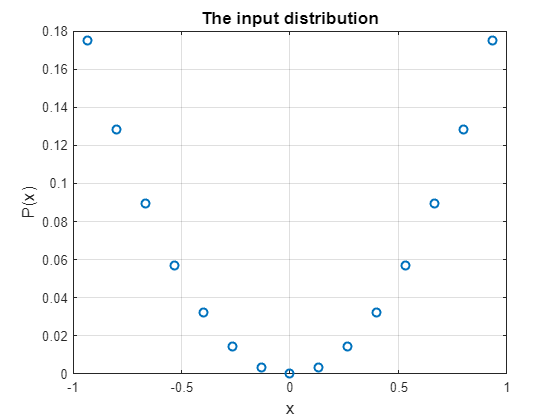

% The variance vector of Laplace mechanism
VarLaplace = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    VarLaplace(i) = 8/(eps_grid(i))^2;
end

% The variance vector of Duchi mechanism
VarDuchi = zeros(1,length(eps_grid));
VarDuchiWorst = zeros(1,length(eps_grid));
var_duchi = @(ti,eps) ((exp(eps)+1)/(exp(eps)-1)).^2 - ti.^2;
for i = 1:length(eps_grid)
    temp = var_duchi(x_grid,eps_grid(i));
    VarDuchi(i) = temp *x_P';
    VarDuchiWorst(i) = max(temp);
end

% The variance vector of piece-wise mechanism
VarPiecewise = zeros(1,length(eps_grid));
VarPiecewiseWorst = zeros(1,length(eps_grid));
var_piecewise = @(ti,eps) ti.^2./(exp(eps/2)-1) + (exp(eps/2)+3)/3/(exp(eps/2)-1)^2;
for i = 1:length(eps_grid)
    temp = var_piecewise(x_grid,eps_grid(i));
    VarPiecewise(i) = temp *x_P';
    VarPiecewiseWorst(i) = max(temp);
end

% The variance vector of Hybrid mechanism
VarHybrid = zeros(1,length(eps_grid));
VarHybridWorst = zeros(1,length(eps_grid));
alpha = @(eps) sign(max(eps-0.61,0))*(1-exp(-eps/2));
var_hybrid = @(ti,eps) alpha(eps)*var_piecewise(ti,eps) + (1-alpha(eps))*var_duchi(ti,eps);
for i = 1:length(eps_grid)
    temp = var_hybrid(x_grid,eps_grid(i));
    VarHybrid(i) = temp *x_P';
    VarHybridWorst(i) = max(temp);
end

% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",FontSize=13);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on

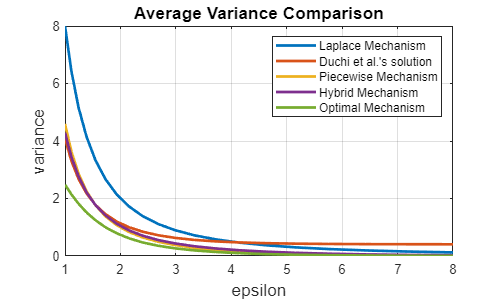

figure;
f = figure;
f.Position = [0 0 500 300];

plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchi,LineWidth=2);
hold on
plot(eps_grid,VarPiecewise,LineWidth=2);
hold on
plot(eps_grid,VarHybrid,LineWidth=2);
hold on
plot(eps_grid,VarOpt,LineWidth=2);

title("Average Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

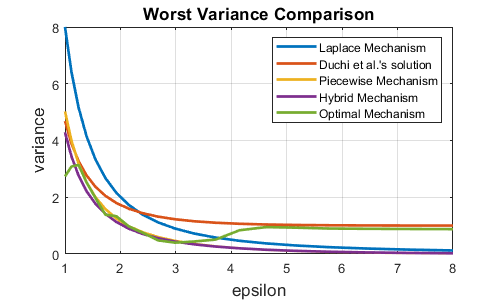

figure;
f = figure;
f.Position = [0 0 500 300];

plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchiWorst,LineWidth=2);
hold on
plot(eps_grid,VarPiecewiseWorst,LineWidth=2);
hold on
plot(eps_grid,VarHybridWorst,LineWidth=2);
hold on
plot(eps_grid,VarOptWorst,LineWidth=2);
title("Worst Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

% Please be advised this section is another experiment.

q = 10; % quantization level
% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 4; %the ratio amax/xmax
eps = 2; % the privacy parameter


xmax = 1;
M = 11; % Total number of bins in [-xmax,xmax]
x_bin_size = 2*xmax/M;
x_grid = linspace(-xmax+0.5*x_bin_size,xmax-0.5*x_bin_size,M);

% xmax = 1;
% xmax = floor(xmax*q)/q; % We need to make sure they are integers
% M = 2*xmax*q+1; % total amount of x samples
% x_grid = linspace(-xmax,xmax,M);

% We assign a distribution to X\in x_grid

x_P = ones(1,M)/M; % Uniform distribution

% x_P = x_grid.^2;
% x_P = x_P./ sum(x_P);

% x_P = x_grid-min(x_grid);
% x_P = x_P./sum(x_P);

[varVector,pMatrix,a_grid] =...
    opt_variance(eps,delta,r,axRatio,x_grid,x_P);

--------------------------------
eps = 2.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.2603   -0.0950   -0.2166   -0.0134   -0.0023   -0.1943   -0.0103         0   -0.1153   -0.0761   -0.1952


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.8108    0.7446    0.6855    0.6194    0.5401    0.4410    0.5401    0.6194    0.6855    0.7446    0.8108


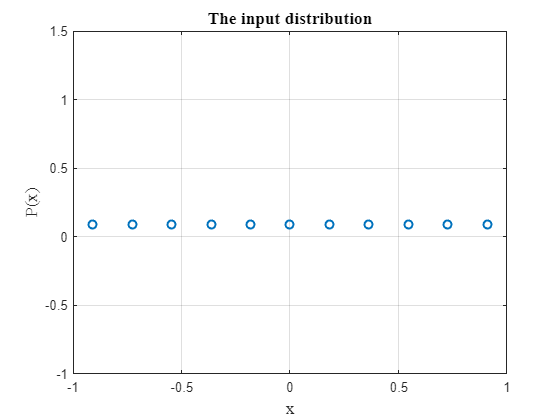

% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",'FontSize',13,'FontName','Times');
xlabel("x",'FontSize',13,'FontName','Times');
ylabel("P(x)",'FontSize',13,'FontName','Times');
grid on

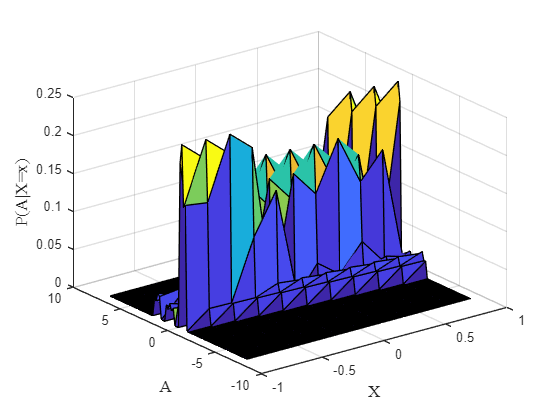


figure
[X_grid,Y_grid] = meshgrid(-x_grid,a_grid);
surf(X_grid,Y_grid,pMatrix');
xlabel("X",'FontSize',13,'FontName','Times');
ylabel("A",'FontSize',13,'FontName','Times');
zlabel("P(A|X=x)",'FontSize',13,'FontName','Times');